# model Generator

This script is intended to service as an example of how to load processed feature data and construct a statistical model from it. The confusion matrix will be saved to a csv file. 

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamples' directory. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR10Octaves";

% Model storage directory and file name
modeldir = fullfile(basedir,'data','Models');
modelfilename = "ModelSNR10OctaveLogistic";

modelresultscsv = "ModelResults.csv";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc


## Model parameters

List and define model parameters.

% model type
type = "logistic";

% probability threshold for contaminated class
pthresh = 0.5;

% # cross-validation folds
KFolds = 10;

## Load features

Load the features table from the processed data. 

% Load feature table
features = load(fullfile(featuredir,featurefilename));
xfeatures = features.xfeatures;

## Define model

Define the model and any optional parameters. Use the fitglm function to train a logistic regression model without regularization or use the lassoglm function to fit a logistic regression model with regularization. 

% Fit logistic model for all data
fitModel = @(data) fitglm(data,'Distribution','binomial','link','logit');
mdl = fitModel(xfeatures);


% Perform cross-validation
cvp = cvpartition(xfeatures.contaminated,'KFold',KFolds); % Stratified by default

% Initialize the predictions to the proper sizes
validationPredictions = xfeatures.contaminated;
numObservations = height(xfeatures);
numClasses = 2;
validationScores = NaN(numObservations, numClasses);
for ifold = 1:KFolds
    % Train fold classifier
    foldModel = fitModel(xfeatures(cvp.training(ifold),:));
    
    % Make predictions on testing set
    testP = predict(foldModel,xfeatures(cvp.test(ifold),:));
    foldPredict = testP >= pthresh;
    
    % Store predictions in the original order
    validationPredictions(cvp.test(ifold)) = foldPredict;
end

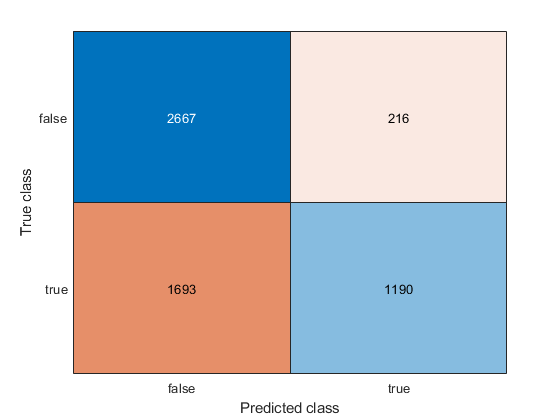


% Create confusion matrix chart
confMat = confusionmat(logical(xfeatures.contaminated),logical(validationPredictions));
accuracyFrac = sum(diag(confMat))/sum(confMat(:));
cm = confusionchart(logical(xfeatures.contaminated),logical(validationPredictions));

## Save output

Save the fitted model and write results to csv file. 

% Save to file
save(fullfile(modeldir,modelfilename))

% Write results to csv file
fid = fopen(fullfile(modeldir,modelresultscsv),'a');
fspec = '%s,%s,%s,%s,%17.15f,%i,%i,%i,%i \n';
fprintf(fid,fspec,type,modelfilename,features.type,features.featurefilename,accuracyFrac,confMat(1,1),confMat(2,1),confMat(1,2),confMat(2,2));
fclose(fid);